clc
clear

### 4-5-2


[mefsin, Fs] = audioread('mefsin.wav');
%sound(mefsin, Fs)

f = Fs*(0:(length(mefsin) - 1))/length(mefsin)

f = 	1.0e+04 *

         0    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0003    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0005    0.0005


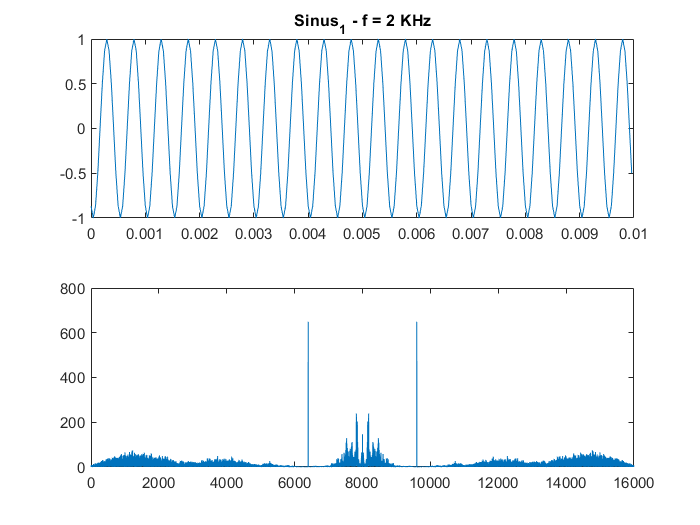

mefsin_spectrum = abs(fftshift(fft(mefsin)));
plot(f, mefsin_spectrum)



x1 = [1 -1.6 1];
x2 = 1;

mefsin_filtered = filter(x1, x2, mefsin);
%sound(filtered_mefsin, Fs);

mefsin_filtered_spec = abs(fftshift(fft(mefsin_filtered)));
plot(f, mefsin_filtered_spec)

### 4-5-3

Fs = 24000;
freq_1 = 2000;
freq_2 = 5000;

[signal1 , ~] = signal_generator(freq_1, Fs);
filewriter(signal1, 'sinus_1.txt')

[signal2 , ~] = signal_generator(freq_2, Fs);
filewriter(signal2, 'sinus_2.txt')

Fs = 24000;
noise = wgn(1,length(signal2),0);
signal_noisy = signal2 + noise;


Terminate = 1;

sin1_filtered = fscanf(fopen('sin1_output.txt', 'r'), "%f ", [Fs*Terminate, 1]);
fclose(fopen('sin1_output.txt', 'r'));

sin2_filtered = fscanf(fopen('sin2_output.txt', 'r'), "%f ", [Fs*Terminate, 1]);
fclose(fopen('sin2_output.txt', 'r'));

t = (0:(1/Fs):(Terminate/100)); % seconds
t = t(1:end - 1);
size(sin2_filtered)

ans =      1     1


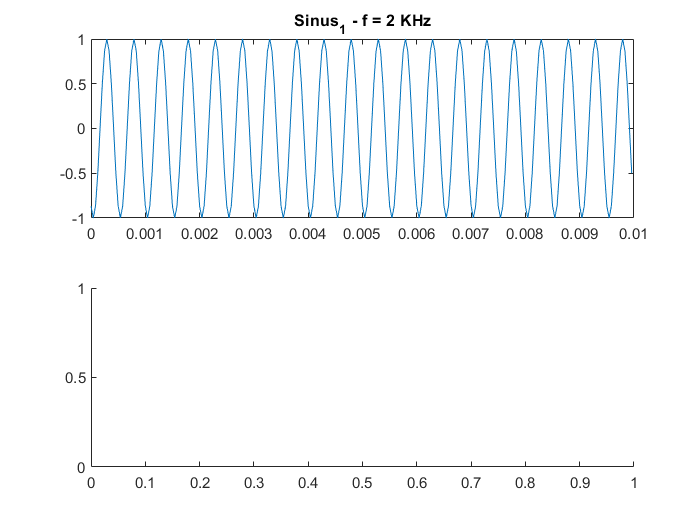

Index exceeds the number of array elements (1).

%size(t)
figure,
subplot(2, 1, 1), plot(t, sin1_filtered(240:479)), title('Sinus_1 - f = 2 KHz');
subplot(2, 1, 2), plot(t, sin2_filtered(240:479)), title('Sinus_2 - f = 5 KHz');